# Seminarski zadatak

### Parametri sustava

global Kv omegav ps pa B V0 qrm J b c Km Kr
Kv = 5.55e-7;   % Koeficijent pojačanja proporcionalnog ventila 
omegav = 113;   % Vlastita frekvencija proporcionalnog ventila
ps = 100e5;     % Tlak napajanja
pa = 1e5;       % Tlak spremnika
B = 1350e6;     % Modul stišljivosti ulja
V0 = 150e-6;    % Poluvolumen motora
qrm = 25.6e-6;  % Specifični protok motora
J = 0.00156;    % Moment inetcije tereta
b = 0.5;        % Koeficijent prigušenja tereta (trenje)
c = 150;        % Koeficijent elastičnosti tereta
Km = 1;         % Koeficijent povratne veze
Kr = 1;         % Pojačanje P regulatora

### Simulink model

sim("seminar_simulink0.slx", 4);

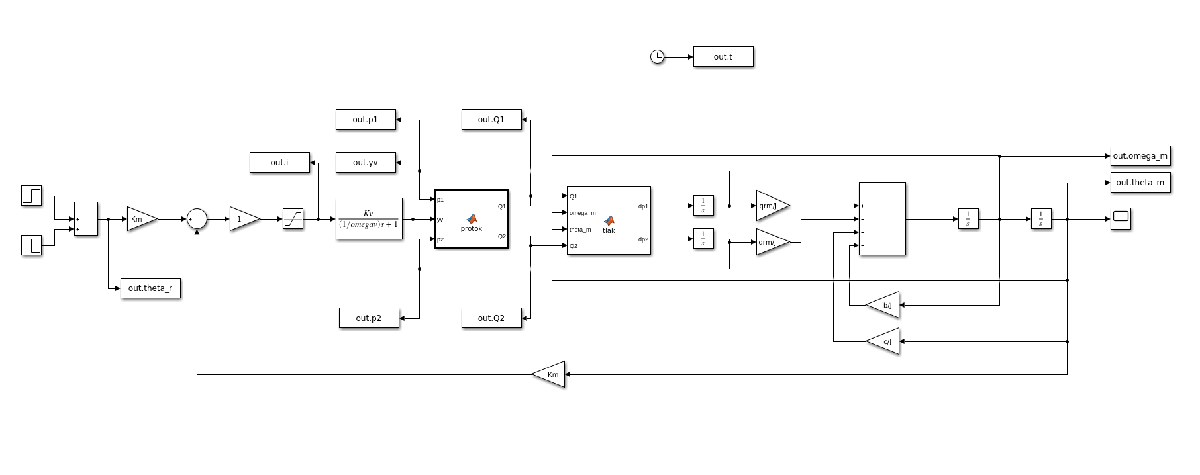

### Simulacijski rezultati

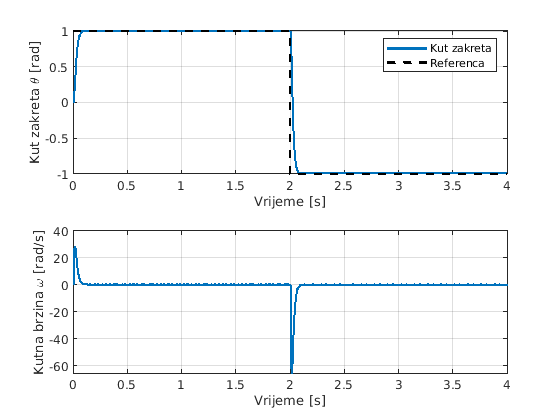

figure
subplot(2,1,1);
plot(out.t, out.theta_m, 'LineWidth', 2);
hold on
plot(out.t, out.theta_r, 'k--', 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Kut zakreta \theta [rad]');
legend('Kut zakreta', 'Referenca');

subplot(2,1,2);
plot(out.t, out.omega_m, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Kutna brzina \omega [rad/s]');

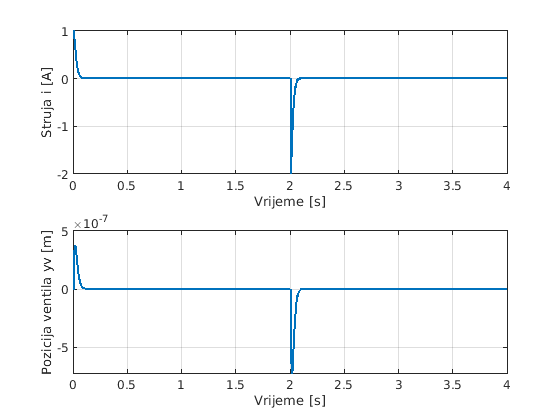

%plot 2
figure
subplot(2,1,1);
plot(out.t, out.i, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Struja i [A]');

subplot(2,1,2);
plot(out.t, out.yv, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Pozicija ventila yv [m]');

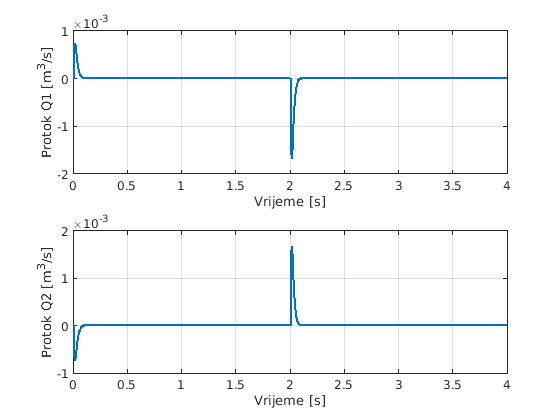

%plot 3
figure
subplot(2,1,1);
plot(out.t, out.Q1, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Protok Q1 [m^3/s]');

subplot(2,1,2);
plot(out.t, out.Q2, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Protok Q2 [m^3/s]');

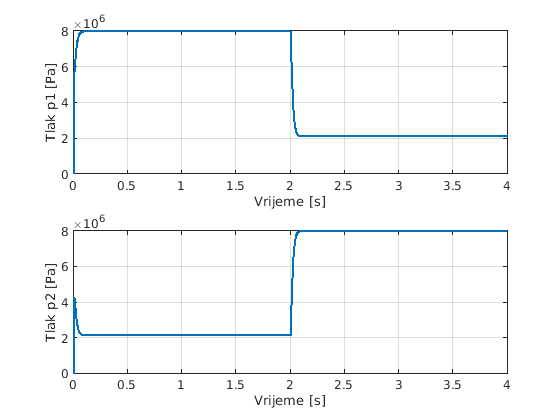

%plot 4
figure
subplot(2,1,1);
plot(out.t, out.p1, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Tlak p1 [Pa]');

subplot(2,1,2);
plot(out.t, out.p2, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Tlak p2 [Pa]');